## Canadian GP 2023 Race Strategy Analysis

Canada_Race = readtable('Laptime CSV Data/2023 Season/CanadaGP/2023 CanadaGP LapTimes.csv');

## Create Visualisations for Race Strategy and Times

Plotting the laptimes and trends for the Albon and Ocon, as well as Hamilton, Sainz and Leclerc.

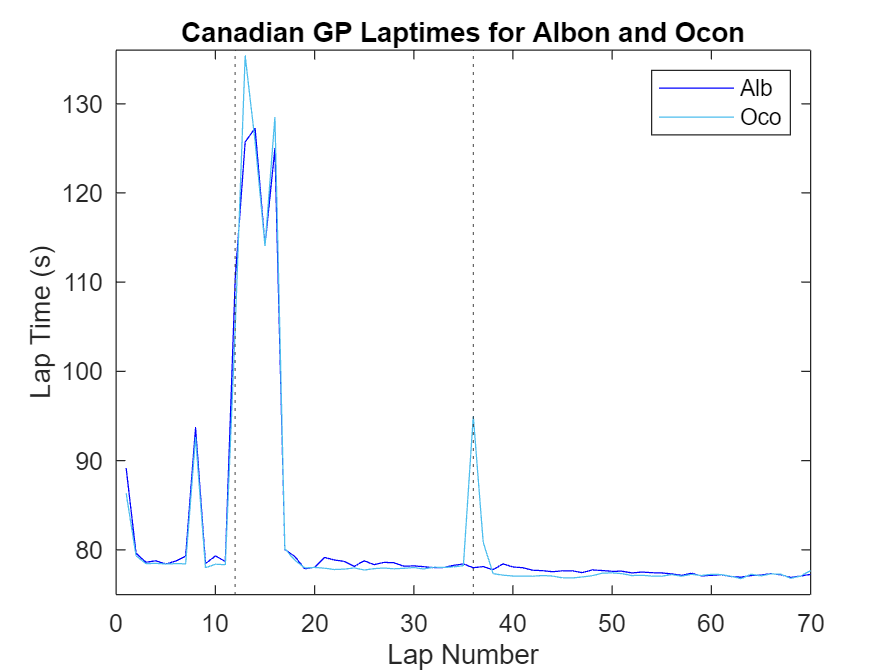

AA_laptimes = table2array(Canada_Race(:,9));
EO_laptimes = table2array(Canada_Race(:,10));

LH_laptimes = table2array(Canada_Race(:,11));
CS_laptimes = table2array(Canada_Race(:,12));
CL_laptimes = table2array(Canada_Race(:,13));

lap_number = 1:70;
AA_EO_race_laptimes = [AA_laptimes EO_laptimes];
LH_CS_CL_race_laptimes = [LH_laptimes CS_laptimes CL_laptimes];

plot(lap_number,AA_EO_race_laptimes)
xline([12, 36],":")
colororder(["#0000FF"; "#4DBEEE"])
title("Canadian GP Laptimes for Albon and Ocon")
xlabel("Lap Number")
ylabel("Lap Time (s)")
ylim([75 136])
legend(["Alb" "Oco"])

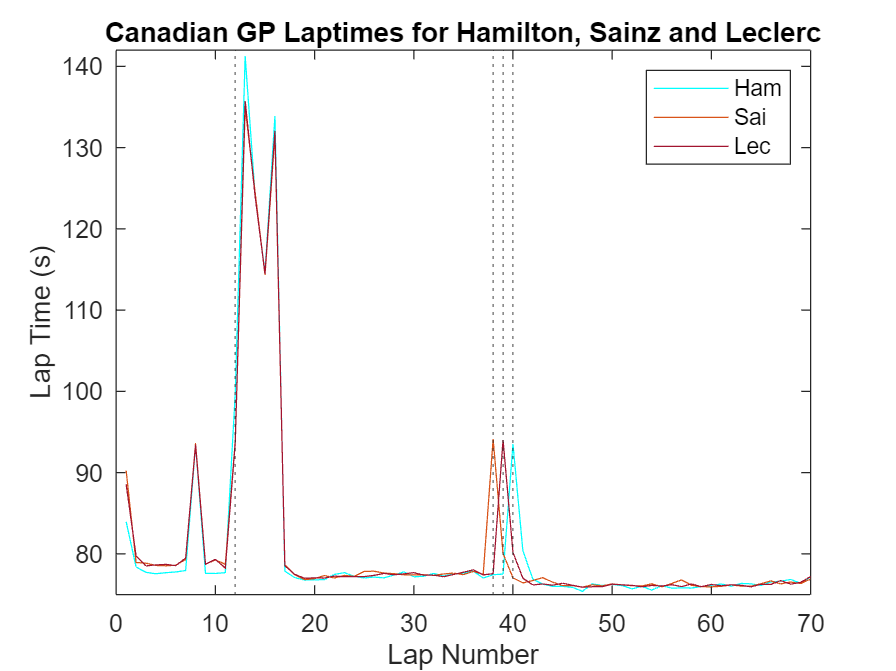


plot(lap_number,LH_CS_CL_race_laptimes)
xline([12, 38, 39, 40],":")
colororder(["#00FFFF"; "#D95319"; "#A2142F"])
title("Canadian GP Laptimes for Hamilton, Sainz and Leclerc")
xlabel("Lap Number")
ylabel("Lap Time (s)")
ylim([75 142])
legend(["Ham" "Sai" "Lec"])

## Final Stint Ocon vs Albon Times and Delta

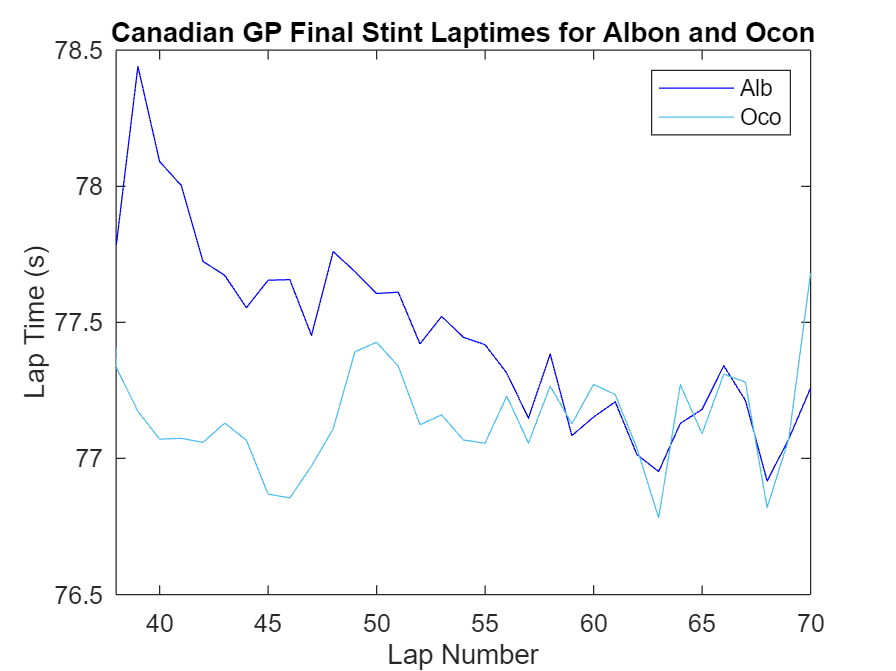

plot(lap_number,AA_EO_race_laptimes)
colororder(["#0000FF"; "#4DBEEE"])
title("Canadian GP Final Stint Laptimes for Albon and Ocon")
xlabel("Lap Number")
ylabel("Lap Time (s)")
xlim([38 70])
ylim([76.5 78.5])
legend(["Alb" "Oco"])

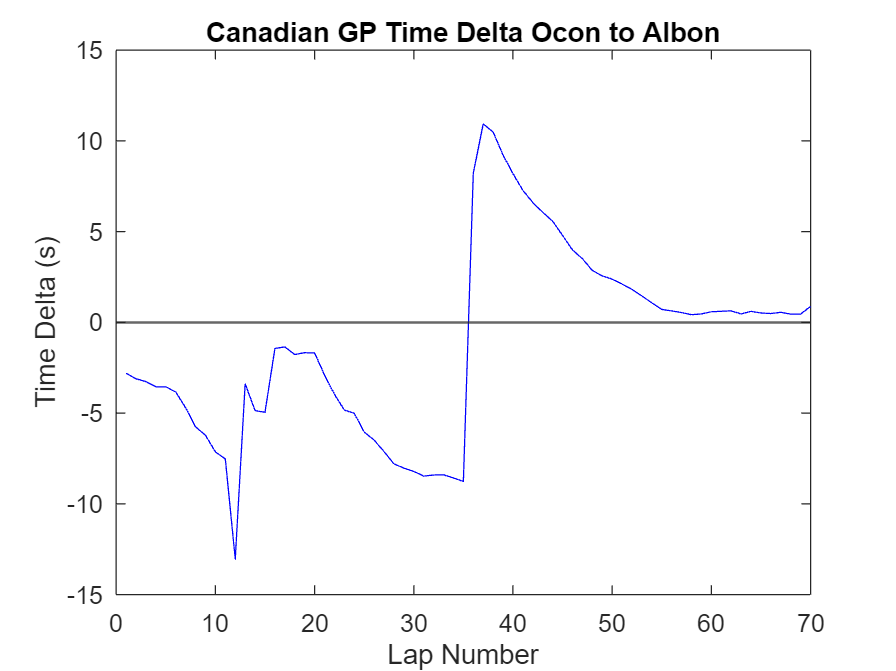


AA_EO_raceDelta = table2array(Canada_Race(:,15));

plot(lap_number,AA_EO_raceDelta)
title("Canadian GP Time Delta Ocon to Albon")
xlabel("Lap Number")
ylabel("Time Delta (s)")
colororder(["#0000FF"; "#4DBEEE"])
yline(0,"LineWidth",1)

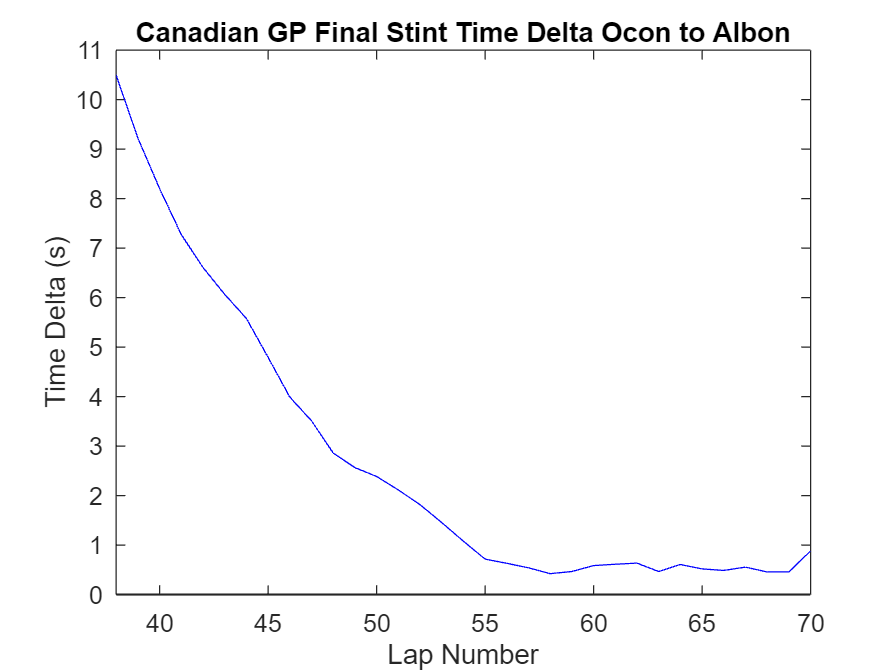


plot(lap_number,AA_EO_raceDelta)
title("Canadian GP Final Stint Time Delta Ocon to Albon")
xlabel("Lap Number")
ylabel("Time Delta (s)")
colororder(["#0000FF"; "#4DBEEE"])
yline(0,"LineWidth",1)
xlim([38 70])
ylim([0 11])

## Time Delta for Hamilton to Sainz and Leclerc

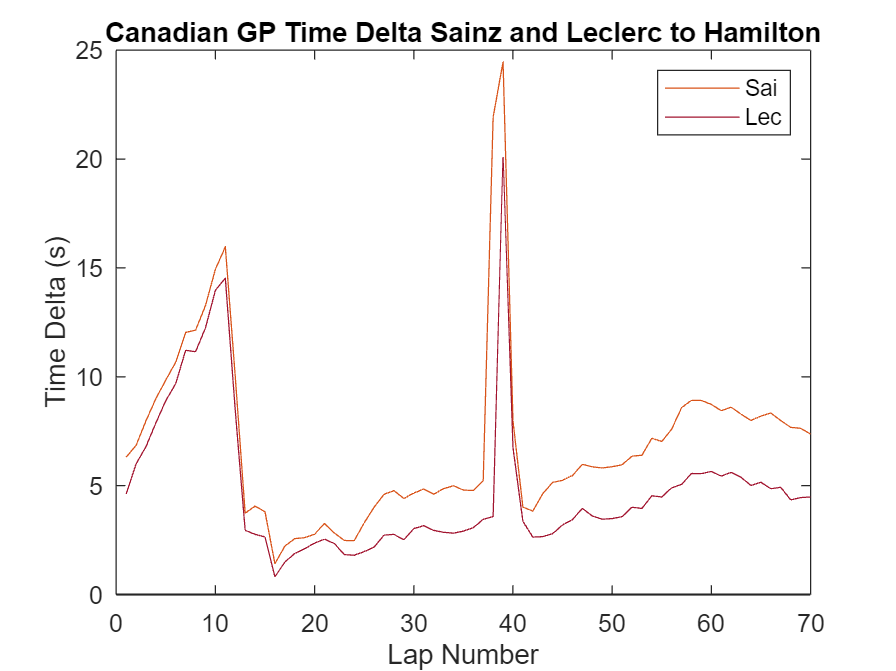

LH_CS_raceDelta = table2array(Canada_Race(:,17));
LH_CL_raceDelta = table2array(Canada_Race(:,18));

LH_Ferrari_Delta = [LH_CS_raceDelta, LH_CL_raceDelta];

plot(lap_number,LH_Ferrari_Delta)
yline(0,"LineWidth",1)
title("Canadian GP Time Delta Sainz and Leclerc to Hamilton")
xlabel("Lap Number")
ylabel("Time Delta (s)")
colororder(["#D95319"; "#A2142F"])
legend(["Sai" "Lec"])